# Create Simple Sequence Classification Network Using Deep Network Designer

This example shows how to create a simple long short-term memory (LSTM) classification network using Deep Network Designer.

To train a deep neural network to classify sequence data, you can use an LSTM network. An LSTM network is a type of recurrent neural network (RNN) that learns long-term dependencies between time steps of sequence data.

The example demonstrates how to:

- Load sequence data.

- Construct the network architecture.

- Specify training options.

- Train the network.

- Predict the labels of new data and calculate the classification accuracy.

## Load Data

Load the Japanese Vowels data set, as described in [1] and [2]. The predictors are cell arrays containing sequences of varying length with a feature dimension of 12. The labels are categorical vectors of labels 1,2,...,9.

load JapaneseVowelsTrainData

Error using load
JapaneseVowelsTrainData is not found in the current folder or on the MATLAB path, but exists in:
    /MATLAB Drive/Examples/R2023b/nnet/CreateSequenceClassificationNetworkInDeepNetworkDesignerExample

Change the MATLAB current folder or add its folder to the MATLAB path.

load JapaneseVowelsTestData

View the sizes of the first few training sequences. The sequences are matrices with 12 rows (one row for each feature) and a varying number of columns (one column for each time step).

XTrain(1:5)

## Define Network Architecture

Open Deep Network Designer.

deepNetworkDesigner

Pause on **Sequence-to-Label** and click **Open**. This opens a prebuilt network suitable for sequence classification problems. 

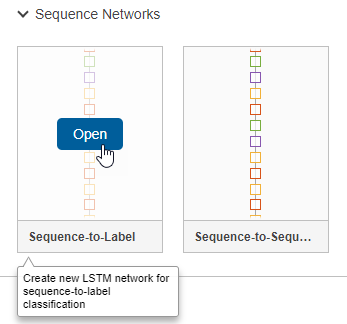

Deep Network Designer displays the prebuilt network. 

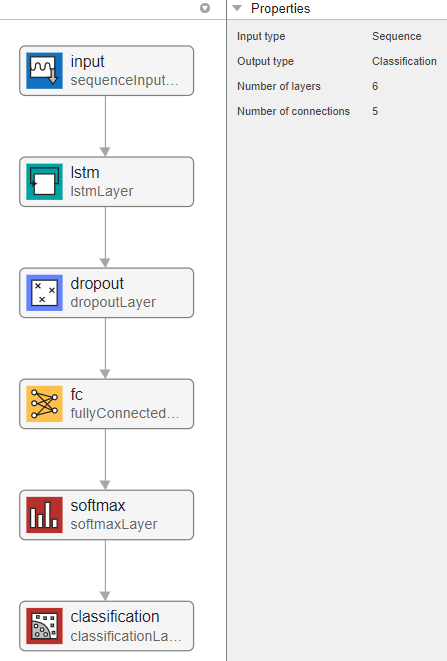

You can easily adapt this sequence network for the Japanese Vowels data set. 

Select **sequenceInputLayer** and check that **InputSize** is set to 12 to match the feature dimension.

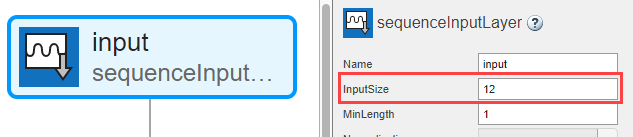

Select **lstmLayer** and set **NumHiddenUnits** to 100. 

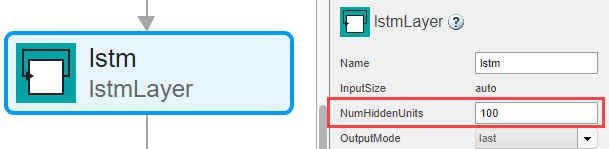

Select **fullyConnectedLayer** and check that **OutputSize** is set to 9, the number of classes.

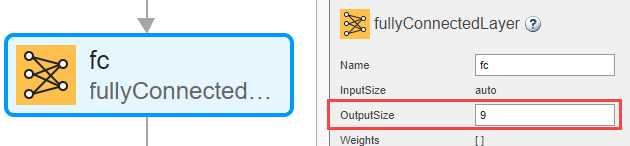

## Check Network Architecture

To check the network and examine more details of the layers, click **Analyze**.

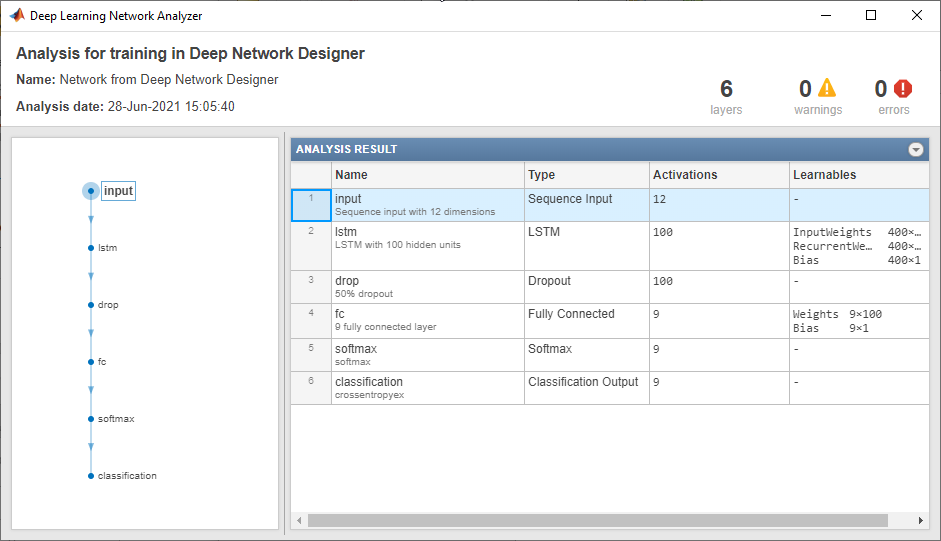

## Export Network Architecture

To export the network architecture to the workspace, on the **Designer** tab, click **Export**. Deep Network Designer saves the network as the variable `layers_1`. 

You can also generate code to construct the network architecture by selecting **Export** > **Generate Network Code Without Parameters**.

## Train Network

Specify the training options and train the network. 

Because the mini-batches are small with short sequences, the CPU is better suited for training. Set `'ExecutionEnvironment'` to `'cpu'`. To train on a GPU, if available, set `'ExecutionEnvironment'` to `'auto'` (the default value).

miniBatchSize = 27;
options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu', ...
    'MaxEpochs',100, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData',{XValidation,TValidation}, ...
    'GradientThreshold',2, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network.

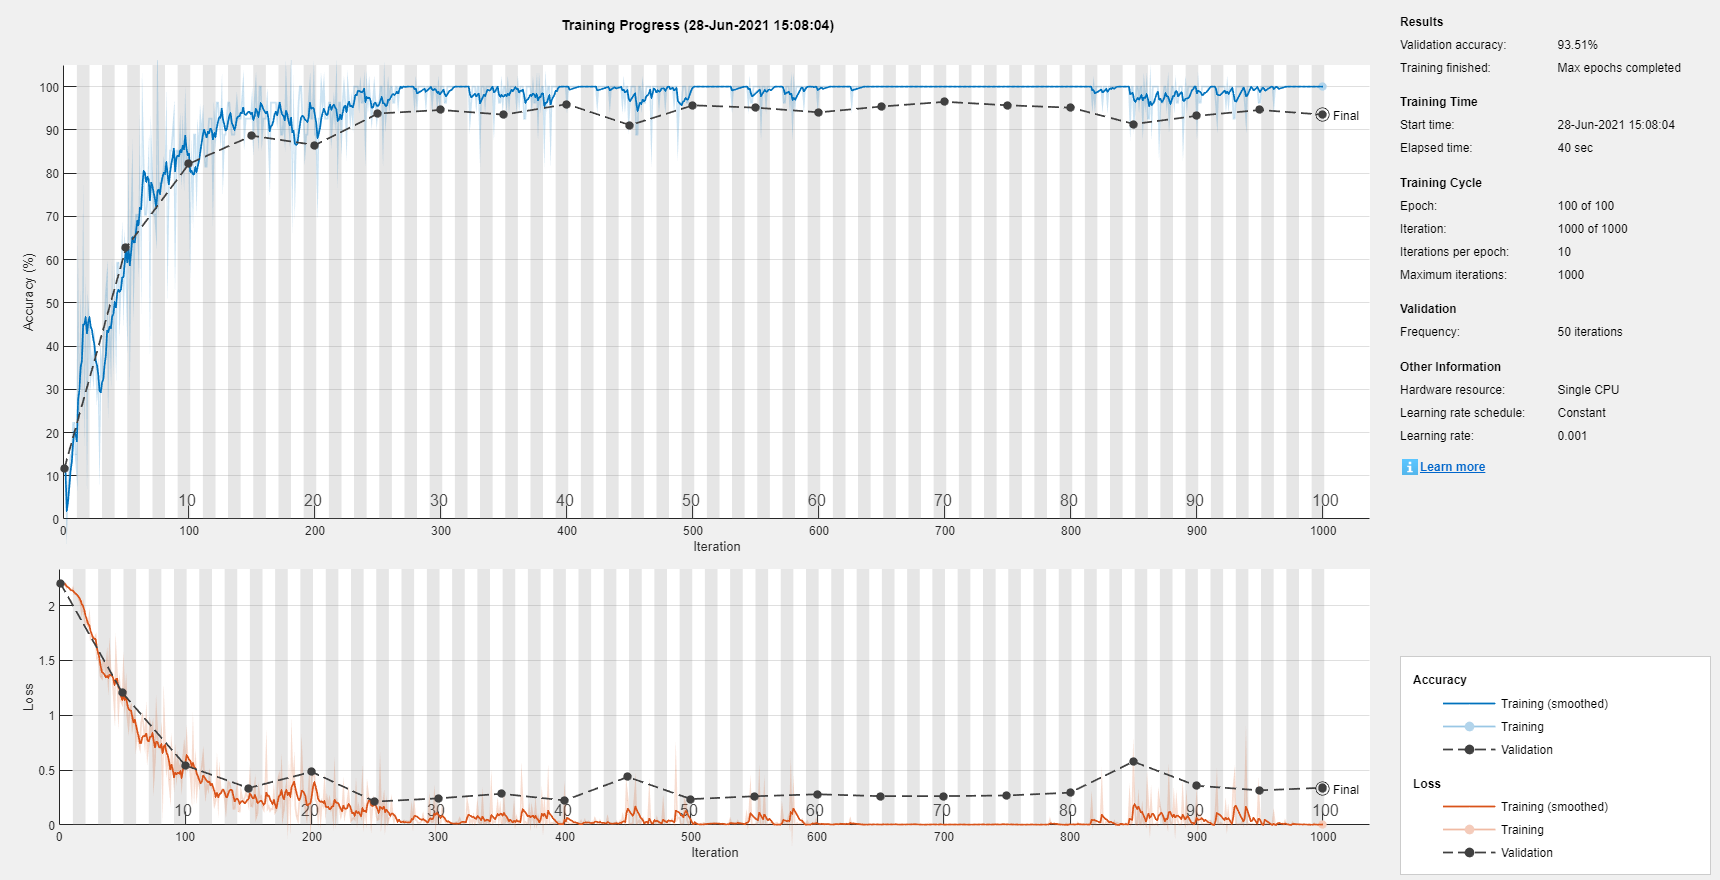

net = trainNetwork(XTrain,TTrain,layers_1,options);

You can also train this network using Deep Network Designer and datastore objects. For an example showing how to train a sequence-to-sequence regression network in Deep Network Designer, see [Time Series Forecasting Using Deep Network Designer](docid:nnet_ug#mw_204e08ac-38cf-4c04-8cc4-96a87d402136).

## Test Network

Classify the test data and calculate the classification accuracy. Specify the same mini-batch size as for training.

YPred = classify(net,XValidation,'MiniBatchSize',miniBatchSize);
acc = mean(YPred == TValidation)

acc = 0.9405

For next steps, you can try improving the accuracy by using bidirectional LSTM (BiLSTM) layers or by creating a deeper network. For more information, see [Long Short-Term Memory Networks](docid:nnet_ug#mw_b9c3c9b2-62d9-47fa-8105-0e940fb4ac08). 

For an example showing how to use convolutional networks to classify sequence data, see [Speech Command Recognition Using Deep Learning](docid:nnet_ug#mw_10daaf69-9f35-4bf2-968b-c38e51a458e0).

## References

[1] Kudo, Mineichi, Jun Toyama, and Masaru Shimbo. “Multidimensional Curve Classification Using Passing-through Regions.” Pattern Recognition Letters 20, no. 11–13 (November 1999): 1103–11. https://doi.org/10.1016/S0167-8655(99)00077-X.

[2] Kudo, Mineichi, Jun Toyama, and Masaru Shimbo. Japanese Vowels Data Set. Distributed by UCI Machine Learning Repository. [https://archive.ics.uci.edu/ml/datasets/Japanese+Vowels](https://archive.ics.uci.edu/ml/datasets/Japanese+Vowels)

*Copyright 2019-2023 The MathWorks, Inc.*